# 第2章 离散时间信号和系统分析基础

## 2.2 连续时间信号的采样及采样定理

### 2.2.2 采样定理

#### `Ch2_2_1`

`模拟信号`$x_a \left(t\right)=\sin \left(2\pi \ast f_1 \ast t\right)+\cos \left(2\pi \ast f_2 \ast t\right)$`，`$f_1 =1\textrm{Hz},\;f_2 =2\textrm{Hz}$`，以`$f_s =16\textrm{Hz}$`采样`16`点得到数字序列`$x\left(n\right)$`。`

`画出模拟信号、模拟信号采样、数字序列。`

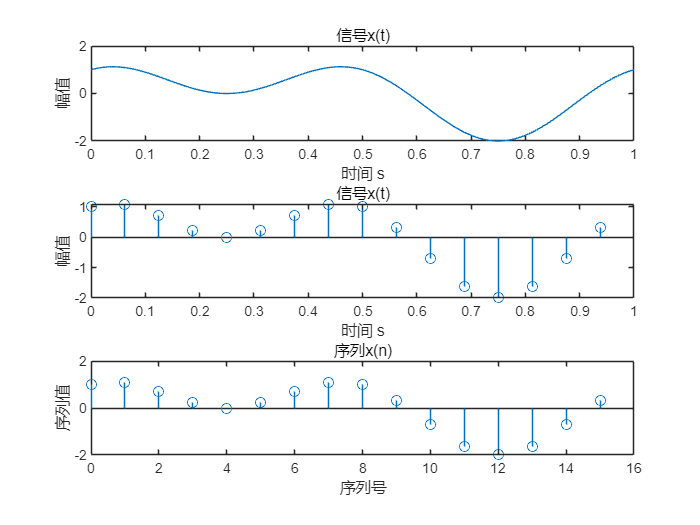

fs = 16; %Hz 
f1 = 1;  %Hz
f2 = 2;  %Hz
N = 16;
n = 0:1:15;
dt = 0.001; %仿真步长：0.001s
t = 0:dt:1; %仿真时长：2s
xt = sin(2*pi*f1*t) + cos(2*pi*f2*t);
%模拟信号
subplot(3,1,1);plot(t,xt);xlim([0 1]);ylim([-2 2]);
xlabel('时间 s');ylabel('幅值');title('信号x(t)');
%模拟信号采样
subplot(3,1,2);plot(t,xt);xlim([0 1]);ylim([-2 2]);
%增加采样点，便于观察；采样频率10Hz，采样间隔0.1s
x = sin(2*pi*(f1/fs)*n)+cos(4*pi*(f1/fs)*n);
stem(n/16,x);xlabel('时间 s');ylabel('幅值');title('信号x(t)')
%数字序列
subplot(3,1,3);stem(n,x);xlim([0 16]);ylim([-2 2]);
xlabel('序列号');ylabel('序列值');title('序列x(n)')